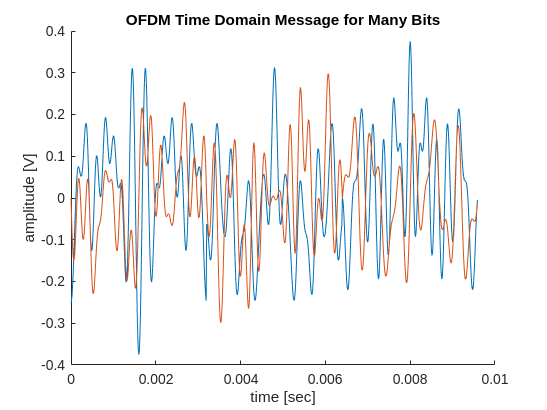

% Adam Nichols
% Prof. Jacobs
% ECE 1898
% 3 February 2025

% modulate/demodulate a message using a simple OFDM scheme

% reset the workspace
clear, clc

% generate a message of random bits
num_bits = 96;
bits = RandomBits(num_bits);

% parallelize bits into bitstreams
num_carriers = 32;
num_OFDM_symbols = ceil(num_bits / num_carriers);
if mod(num_bits,num_carriers) > 0
    bits_padded = [bits; zeros(num_carriers-mod(num_bits,num_carriers),1)];
else
    bits_padded = bits;
end

OFDM_data = reshape(bits_padded,num_carriers,[]);

% modulate OFDM symbols from the fourier coefficients
fourier_coeffs = OFDM_data*2 - 1;
s_t = zeros(num_carriers,num_OFDM_symbols);
% perform IFFT
for i = 0:num_OFDM_symbols-1
    s_t(i*num_carriers+1:(i+1)*num_carriers) = ifft(fourier_coeffs(i*num_carriers+1:(i+1)*num_carriers));
end

% define timing parameters of the OFDM signal
bandwidth = 1e4;
OFDM_samplerate = bandwidth;
OFDM_sampleperiod = 1/OFDM_samplerate;
OFDM_symboltime = OFDM_sampleperiod * num_carriers;
OFDM_symbolrate = 1/OFDM_symboltime;
t = transpose((0:num_carriers*num_OFDM_symbols-1)*OFDM_sampleperiod);

% perform upsampling
upsamp = 8;
s_t_upsamp = zeros(num_carriers*upsamp,num_OFDM_symbols);
for i = 0:num_OFDM_symbols-1
    s_t_curr = s_t(i*num_carriers+1:(i+1)*num_carriers);
    if num_OFDM_symbols > 1
        s_t_curr = transpose(s_t_curr);
    end
    s_t_curr_triple = [s_t_curr; s_t_curr; s_t_curr];
    s_t_curr_triple_upsamp = resample(s_t_curr_triple,upsamp,1);
    s_t_curr_upsamp = s_t_curr_triple_upsamp(upsamp*num_carriers+1:2*upsamp*num_carriers);
    s_t_upsamp((i*num_carriers*upsamp+1:(i+1)*num_carriers*upsamp)) = s_t_curr_upsamp;
end
OFDM_samplerate_upsamp = upsamp*OFDM_samplerate;
OFDM_sampleperiod_upsamp = OFDM_sampleperiod/upsamp;
t_upsamp = transpose((0:num_carriers*num_OFDM_symbols*upsamp-1)*OFDM_sampleperiod_upsamp);

% concatenate all OFDM symbols without guard intervals or filtering
s_t_upsamp_vec = reshape(s_t_upsamp,[],1);

% plot this upsampled, concatenated version of OFDM
figure(1)
clf
hold on
plot(t_upsamp,real(s_t_upsamp_vec))
plot(t_upsamp,imag(s_t_upsamp_vec))
title("OFDM Time Domain Message for Many Bits")
xlabel("time [sec]")
ylabel("amplitude [V]")

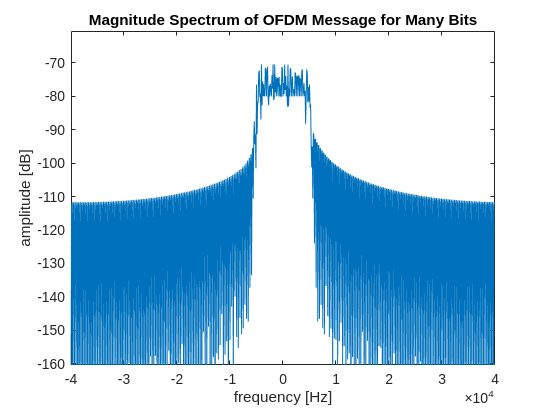


% get the spectrum of the concatednated signal
[f_upsamp_all, spec_upsamp_all] = GetSpectrum(s_t_upsamp_vec,OFDM_samplerate_upsamp);
mag_spec_upsamp_all = 20*log10(abs(spec_upsamp_all));

% plot the spectrum of the upsampled signal
figure(2)
clf
plot(f_upsamp_all,mag_spec_upsamp_all)
title("Magnitude Spectrum of OFDM Message for Many Bits")
xlabel("frequency [Hz]")
ylabel("amplitude [dB]")
ylim([max(mag_spec_upsamp_all)-90, max(mag_spec_upsamp_all)+10])

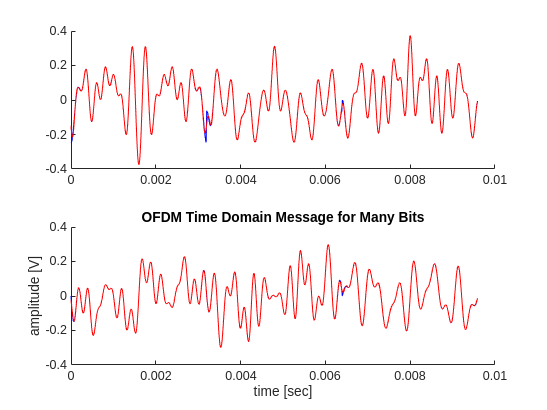


% pass the OFDM through a lowpass to meet channel specs
s_t_upsamp_lp = lowpass(s_t_upsamp_vec,bandwidth/OFDM_samplerate_upsamp);
[~, spec_upsamp_lp] = GetSpectrum(s_t_upsamp_lp,OFDM_samplerate_upsamp);
mag_spec_upsamp_lp = 20*log10(abs(spec_upsamp_lp));

% plot the lowpassed version on same axes as original to show distortion
figure(3)
clf
tiledlayout
nexttile
hold on
plot(t_upsamp,real(s_t_upsamp_vec),'b-')
plot(t_upsamp,real(s_t_upsamp_lp),'r-')
nexttile
hold on
plot(t_upsamp,imag(s_t_upsamp_vec),'b-')
plot(t_upsamp,imag(s_t_upsamp_lp),'r-')
title("OFDM Time Domain Message for Many Bits")
xlabel("time [sec]")
ylabel("amplitude [V]")

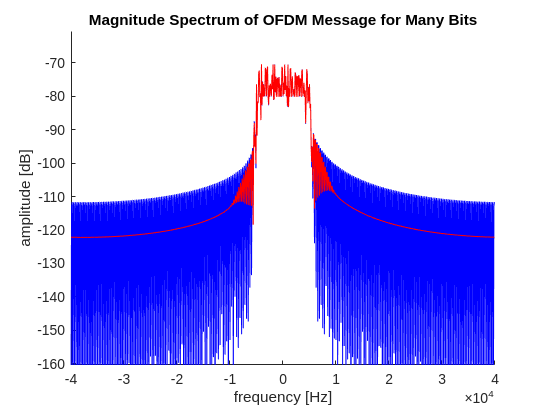


% plot the spectrum of the upsampled signal and the lowpassed version
figure(4)
clf
hold on
plot(f_upsamp_all,mag_spec_upsamp_all, 'b-')
plot(f_upsamp_all,mag_spec_upsamp_lp, 'r-')
title("Magnitude Spectrum of OFDM Message for Many Bits")
xlabel("frequency [Hz]")
ylabel("amplitude [dB]")
ylim([max(mag_spec_upsamp_all)-90, max(mag_spec_upsamp_all)+10])

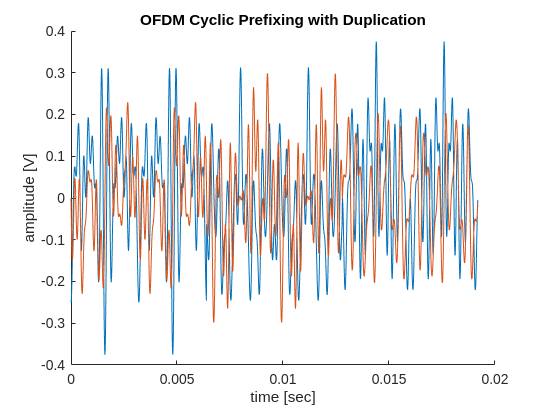




% perform cyclic prefixing to reduce spurious emission
% duplicate each symbol for a cyclic prefix, shorten later
t_prefix = transpose((0:num_carriers*num_OFDM_symbols*upsamp*2-1)*OFDM_sampleperiod_upsamp);
[s_t_upsamp_symbol_length, s_t_upsamp_num_symbols] = size(s_t_upsamp);
s_t_prefix = [];
for i = 1:num_OFDM_symbols
    s_t_prefix = [s_t_prefix; s_t_upsamp(1:s_t_upsamp_symbol_length, i); s_t_upsamp(1:s_t_upsamp_symbol_length, i)];
end

% plot the prefix version of s(t)
figure()
clf
hold on
plot(t_prefix,real(s_t_prefix))
plot(t_prefix,imag(s_t_prefix))
title("OFDM Cyclic Prefixing with Duplication")
xlabel("time [sec]")
ylabel("amplitude [V]")


% pass this prefixed version through a lowpass filter
s_t_prefix_lp = lowpass(s_t_prefix,bandwidth/OFDM_samplerate);

Error using signal.internal.filteringfcns.parseAndValidateInputs>validateParameters (line 229)
Normalized passband frequency values must be in the (0,1) interval. Use a value in the (0,1) interval or specify a sample rate.

Error in signal.internal.filteringfcns.parseAndValidateInputs (

## Functions:

% GetSpectrum gets the spectrum of the input signal
% uses the fftshift function to make DC appear at center term
function [f,spectrum] = GetSpectrum(samples, sample_rate)

    % determine the spectrum of the baseband signal
    spectrum = 1/sample_rate*fftshift(fft(samples));
    
    % get bin numbers (centered at 0)
    f_bins = (0:length(samples)-1) - floor(length(samples)/2);

    % define the frequency range
    f = transpose(f_bins * sample_rate / length(f_bins));
end

function bits = RandomBits(num_bits)
    % create a vector of random bits to the required length
    bits = zeros(num_bits,1);
    for i = 1:num_bits
        bits(i) = randi(2,1)-1;
    end
end